## Problem 2

**Using the tight-binding (LCAO) approach, compute the energy band formed by atomic s-orbitals in an fcc lattice with a monoatomic basis. Plot the energy vs q along L - **$\Gamma$** - X - U - **$\Gamma$

clc
clear
close all

gamma1 = -1;

Gamma = [0, 0, 0];
X = [2*pi, 0, 0];
L = [pi, pi, pi];
U = [2*pi, pi/2, pi/2];
% Since a cancels out when calculating the energy, plus we don't have a
% value to set it to, I'm going to leave it out of this solution.

k_LG = [linspace(L(1), Gamma(1), 100); linspace(L(2), Gamma(2), 100); linspace(L(3), Gamma(3), 100)];
k_GX = [linspace(Gamma(1), X(1), 100); linspace(Gamma(2), X(2), 100); linspace(Gamma(3), X(3), 100)];
k_XU = [linspace(X(1), U(1), 100); linspace(X(2), U(2), 100); linspace(X(3), U(3), 100)];
k_UG = [linspace(U(1), Gamma(1), 100); linspace(U(2), Gamma(2), 100); linspace(U(3), Gamma(3), 100)];

E_LG = 2 * gamma1 * (cos((k_LG(1,:) + k_LG(2,:))/2) + cos((k_LG(1,:) - k_LG(2,:))/2) + ...
    (cos((k_LG(1,:) + k_LG(3,:))/2) + cos((k_LG(1,:) - k_LG(3,:))/2)) + ...
    (cos((k_LG(2,:) + k_LG(3,:))/2) + cos((k_LG(2,:) - k_LG(3,:))/2)));
E_GX = 2 * gamma1 * (cos((k_GX(1,:) + k_GX(2,:))/2) + cos((k_GX(1,:) - k_GX(2,:))/2) + ...
    (cos((k_GX(1,:) + k_GX(3,:))/2) + cos((k_GX(1,:) - k_GX(3,:))/2)) + ...
    (cos((k_GX(2,:) + k_GX(3,:))/2) + cos((k_GX(2,:) - k_GX(3,:))/2)));
E_XU = 2 * gamma1 * (cos((k_XU(1,:) + k_XU(2,:))/2) + cos((k_XU(1,:) - k_XU(2,:))/2) + ...
    (cos((k_XU(1,:) + k_XU(3,:))/2) + cos((k_XU(1,:) - k_XU(3,:))/2)) + ...
    (cos((k_XU(2,:) + k_XU(3,:))/2) + cos((k_XU(2,:) - k_XU(3,:))/2)));
E_UG = 2 * gamma1 * (cos((k_UG(1,:) + k_UG(2,:))/2) + cos((k_UG(1,:) - k_UG(2,:))/2) + ...
    (cos((k_UG(1,:) + k_UG(3,:))/2) + cos((k_UG(1,:) - k_UG(3,:))/2)) + ...
    (cos((k_UG(2,:) + k_UG(3,:))/2) + cos((k_UG(2,:) - k_UG(3,:))/2)));

E = [E_LG; E_GX; E_XU; E_UG];

E =          0   -0.0030   -0.0121   -0.0272   -0.0483   -0.0754   -0.1084   -0.1474   -0.1923   -0.2430   -0.2996   -0.3618   -0.4298   -0.5033   -0.5824   -0.6670   -0.7569   -0.8521   -0.9525   -1.0579   -1.1684   -1.2837   -1.4037   -1.5284   -1.6576   -1.7912   -1.9289   -2.0708   -2.2167   -2.3663   -2.5197   -2.6765   -2.8366   -3.0000   -3.1664   -3.3356   -3.5075   -3.6819   -3.8587   -4.0376   -4.2185   -4.4012   -4.5854   -4.7712   -4.9581   -5.1461   -5.3350   -5.5245   -5.7145   -5.9048


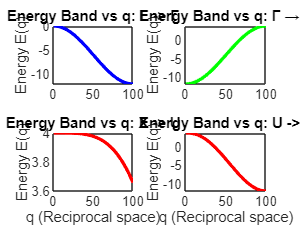

E = E(:);

figure;
hold on;
grid on;
% L -> Γ
subplot(2, 2, 1);
plot(E_LG, 'b', 'LineWidth', 2);
title('Energy Band vs q: L -> Γ');
ylabel('Energy E(q)');

% Γ -> X
subplot(2, 2, 2);
plot(E_GX, 'g', 'LineWidth', 2);
title('Energy Band vs q: Γ → X');
ylabel('Energy E(q)');

% X -> U
subplot(2, 2, 3);
plot(E_XU, 'r', 'LineWidth', 2);
title('Energy Band vs q: X -> U');
xlabel("q (Reciprocal space)");
ylabel('Energy E(q)');

% U -> Γ
subplot(2, 2, 4);
plot(E_UG, 'r', 'LineWidth', 2);
title('Energy Band vs q: U -> Γ');
xlabel("q (Reciprocal space)");
ylabel('Energy E(q)');
hold off